# 0. 添加路径

currentFolder = pwd;
splitted_str = strsplit(currentFolder,'\');
index = contains(splitted_str,'CableSSB-zh');
if ~any(index)
    error('请进入一个在''CableSSB-zh''内的文件夹')
end
mainpath = '';
for i=1:length(splitted_str)
    if index(i)
        path = join(splitted_str(1:i),'\');
        break
    else
        continue
    end
end
MainPath = genpath(path{1});
addpath(MainPath)

clear all
clc

# 1. 建立桥梁模型

% 协作体系模型
b = CableStayedSuspension_Bridge;
b.build;

Is building a Cable-Stayed Suspension Bridge...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    2.675472e+04    0.000e+00    2.087e+05
目标函数返回了 NaN；正在尝试一个新点...
    1      14    4.818367e+03    0.000e+00    7.251e+04    2.598e-01
目标函数返回了 NaN；正在尝试一个新点...
    2      25    2.729550e+03    0.000e+00    8.569e+03    6.495e-02
    3      37    2.699266e+03    0.000e+00    1.075e+03    8.119e-03
    4      48    2.698644e+03    0.000e+00    6.430e+02    2.030e-03
    5      58    2.698569e+03    0.000e+00    5.832e+02    1.015e-03
    6      65    2.698475e+03    0.000e+00    4.061e+02    4.228e-04
    7      70    2.698408e+03    0.000e+00    2.038e+02    2.157e-04
    8      75    2.698391e+03    0.000e+00    1.026e+02    1.082e-04
    9      80    2.698387e+03    0.000e+00    5.164e+01    5.466e-05
   10      85    2.698386e+03    0.000e+00    2.595e+01    2.780e-05
   11      90    2.6

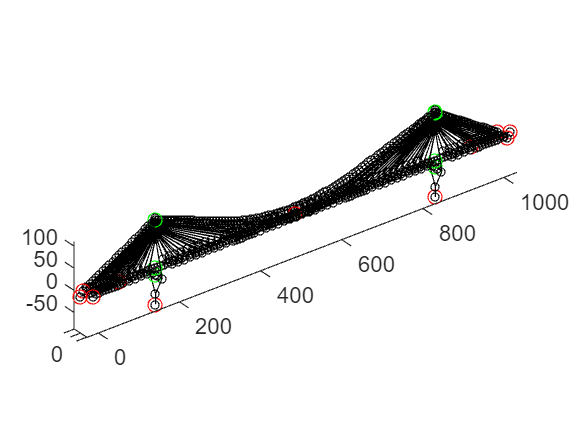

ans =   Figure (4) - 属性:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


b.plot

output_method = OutputToAnsys(b,"JobName",'TotalModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\result.out');
b.OutputMethod = output_method;
b.output

# 2. 计算无索模型的最小弯曲应变能，获得最优设计竖向力

% 无索模型
bridge_state = NoCable_Bridge(b);
bridge_state.build

Is building a Brigde without Cable System...


output_method = OutputToAnsys(bridge_state,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\result.out');
bridge_state.OutputMethod = output_method;
[FEModel,isEquationCompleted] = bridge_state.getFiniteElementModel;

Is getting Finite Element Model from ANSYS...



% 优化弯曲应变能
bridge_state.optimBendingStrainEnergy('MaxIter',25,'DiffMinChange',1e4);

Is optimizing the Bending Strain Energy...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      79    1.427470e+08    0.000e+00    2.034e+01
    1     158    1.427399e+08    0.000e+00    2.034e+01    8.460e+01
    2     237    1.427041e+08    0.000e+00    2.034e+01    4.230e+02
    3     316    1.425254e+08    0.000e+00    2.033e+01    2.115e+03
    4     395    1.416340e+08    0.000e+00    2.026e+01    1.057e+04
    5     474    1.372382e+08    0.000e+00    1.992e+01    5.265e+04
    6     553    1.167441e+08    0.000e+00    1.823e+01    2.587e+05
    7     632    4.649625e+07    0.000e+00    1.053e+01    1.182e+06
    8     711    1.261748e+07    0.000e+00    2.099e+00    1.571e+06
    9     790    1.261739e+07    0.000e+00    2.099e+00    1.019e+01
   10     869    1.261692e+07    0.000e+00    2.099e+00    4.841e+01
   11     948    1.261461e+07    0.000e+00    2.099e+00    2.420e+02
   1

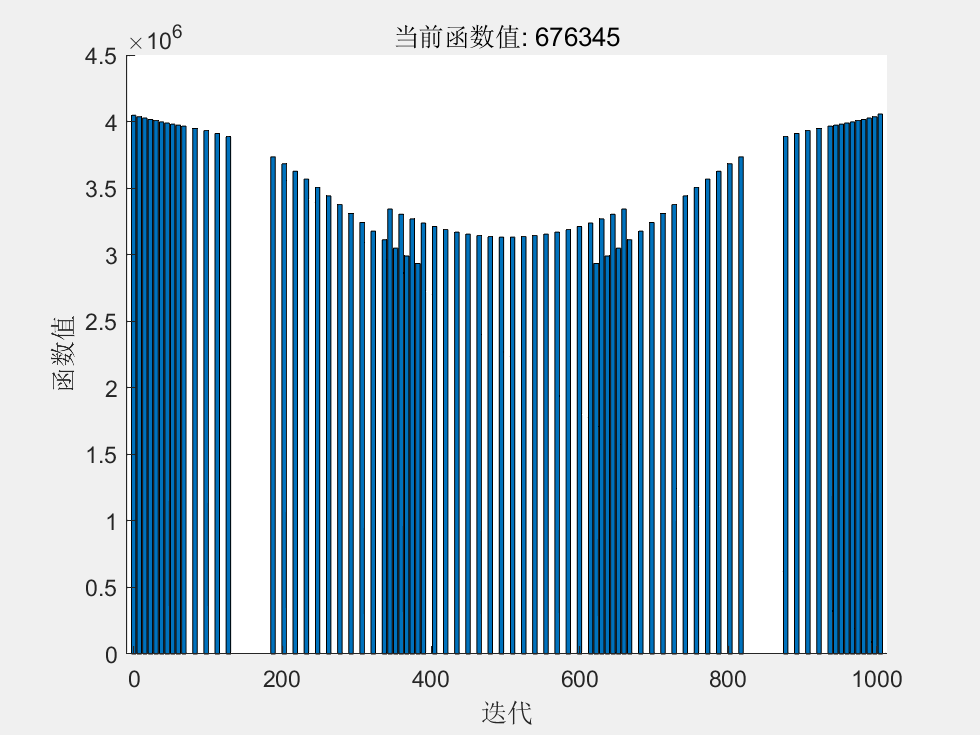


% 结果呈现
Map_Pz = bridge_state.Result_Iteration.Iter_Pz;
max_iter = bridge_state.Iter_Optimization;
Pz_final = Map_Pz(max_iter);
X = bridge_state.OriginalBridge.getSortedGirderPointXCoord([bridge_state.OriginalBridge.findStructureByClass('Hanger'),bridge_state.OriginalBridge.findStructureByClass('StayedCable')]);
bar(X,Pz_final)


% 无索模型的ANSYS结果
output_method = OutputToAnsys(bridge_state,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\result.out');
bridge_state.OutputMethod = output_method;
bridge_state.output

# 3. 根据最优设计竖向力，将无索模型的设计竖向力恢复到吊索、斜拉索、主缆上

% 根据最优设计竖向力Pz_final, 计算此时的斜拉索力、吊索力、主缆内力

% 计算吊索力和主缆内力
bridge_state.solveCableShape(Pz_final);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      23    1.838490e+05    0.000e+00    8.065e+03
    1      46    1.010138e+03    0.000e+00    6.868e+02    2.884e+01
    2      69    1.469223e+02    0.000e+00    2.558e+02    4.200e+00
    3      92    1.577940e+01    0.000e+00    1.905e+01    3.745e+00
    4     116    8.192901e+00    0.000e+00    1.067e+01    1.165e+00
    5     140    2.768678e+00    0.000e+00    1.414e+01    3.248e+00
    6     163    1.111379e+00    0.000e+00    2.020e+00    1.592e+00
    7     186    1.080581e+00    0.000e+00    5.874e+00    1.473e+00
    8     209    3.198430e-01    0.000e+00    1.022e+00    9.063e-01
    9     232    2.854168e-01    0.000e+00    2.801e+00    8.418e-01
   10     255    4.611866e-02    0.000e+00    4.994e-01    4.849e-01

fmincon 已停止，因为目标函数值 4.611866e-02 小于
options

ans = 包含以下字段的 struct :
                   X: [157.2000 164.7000 172.2000 179.7000 187.2000 194.7000 202.2000 209.7000 217.2000 224.7000 232.2000 239.7000 247.2000 254.7000 262.2000 269.7000 277.2000 284.7000 292.2000 299.7000 307.2000 314.7000 322.2000 329.7000 337.2000 … ]
                   Y: [-0.5000 -0.8832 -1.2664 -1.6496 -2.0328 -2.4160 -2.7992 -3.1824 -3.5656 -3.9488 -4.3320 -4.7152 -5.0984 -5.4816 -5.8648 -6.2480 -6.6312 -7.0145 -7.3977 -7.7809 -8.1641 -8.5473 -8.9305 -9.3137 -9.6969 -10.0801 -10.4273 -10.7746 … ]
                   Z: [104.8000 101.7869 98.7789 95.7759 92.7781 89.7854 86.7977 83.8152 80.8377 77.8654 74.8981 71.9359 68.9788 66.0268 63.0799 60.1380 57.2013 54.2696 51.3430 48.4215 45.5050 42.5937 39.6874 36.7862 33.8901 30.9990 28.3775 25.7610 … ]
              Strain: [0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0048

resumeSymmetrical called!



% 计算斜拉索索力
X = bridge_state.XCoordOfPz;
for i=1:length(bridge_state.ReplacedStayedCable)
    stayed_cable = bridge_state.ReplacedStayedCable(i);
    Point_Bottom = stayed_cable.findGirderPoint();
    X_Bottom = [Point_Bottom.X];
    P_girder_z = zeros(1,length(X_Bottom));
    for j=1:length(X)
        index = abs(X(j)-X_Bottom) < 1e-5;
        P_girder_z(index) = Pz_final(j);
    end
    stayed_cable.getP(P_girder_z);
end
% 导出协作体系桥梁模型到ANSYS
b.output

% 检查上述ANSYS模型的各种索力是否与最优设计竖向力匹配，如果不匹配，则需要将其优化至最优设计竖向力

# 检验斜拉索的实常数

temp = b.findStructureByName('StayedCable_1');
StayedCable_1 = temp{1};
temp = b.findStructureByName('StayedCable_3');
StayedCable_3 = temp{1};
temp = b.findStructureByName('StayedCable_5');
StayedCable_5 = temp{1};
temp = b.findStructureByName('StayedCable_7');
StayedCable_7 = temp{1};

% 修改此处，以切换待检查的斜拉索
stayedcable = StayedCable_7;

% epsilon*E*A与InternalForce相等
force = stayedcable.InternalForce;
strain = stayedcable.Strain;
Ex = stayedcable.Material.MaterialData.E;
A = stayedcable.Section.Area;
Ex*A.*strain ./ force % 比较

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0001    1.0001    1.0001    1.0001    1.0001



% 对比defReal.mac中定义的实常数和MATLAB中的应变
format shortE
strain

strain =    1.9238e-03   2.0893e-03   2.2849e-03   2.4989e-03   2.7233e-03   2.8171e-03   2.9092e-03   2.9998e-03   3.0886e-03   3.1759e-03   3.2615e-03   3.3455e-03   3.4279e-03   3.5172e-03


format default

% InternalForce的竖向分量与P_girder_z相等
vertical_force = stayedcable.getVerticalForce;
P_girder_z = stayedcable.Params.P_girder_z;
q = stayedcable.Material.MaterialData.gamma;
L = stayedcable.UnstressedLength;
(vertical_force - A.*q.*L/2) ./ -P_girder_z % 比较

ans =     1.0000    1.0000    1.0000    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001



% 检查P_girder_z是否在P_final中
Pz_final

Pz_final = 1.0e+06 *

    4.0471    4.0365    4.0263    4.0164    4.0069    3.9979    3.9892    3.9810    3.9731    3.9655    3.9490    3.9315    3.9113    3.8872    3.7342    3.6827    3.6271    3.5680    3.5060    3.4418    3.3760    3.3094    3.2427    3.1766    3.1119    3.3430    3.0495    3.3041    2.9903    3.2690    2.9348    3.2381    3.2112    3.1883    3.1692    3.1541    3.1427    3.1352    3.1314    3.1314    3.1352    3.1427    3.1541    3.1692    3.1883    3.2112    3.2381    2.9348    3.2690    2.9903


P_girder_z

P_girder_z = 1.0e+06 *

   -3.8872   -3.9113   -3.9315   -3.9490   -3.9655   -3.9731   -3.9810   -3.9892   -3.9979   -4.0069   -4.0164   -4.0263   -4.0365   -4.0571


# 检查吊索的实常数

temp = b.findStructureByName('Hanger_1');
Hanger_1 = temp{1};
temp = b.findStructureByName('Hanger_2');
Hanger_2 = temp{1};

% 修改此处
hanger = Hanger_2;

% epsilon*E*A与InternalForce相等
force = hanger.InternalForce;
strain = hanger.Strain;
Ex = hanger.Material.MaterialData.E;
A = hanger.Section.Area;
Ex*A.*strain ./ force % 比较

ans =     1.0000    1.0000    1.0000    1.0001    1.0001    1.0001    1.0002    1.0003    1.0005    1.0007    1.0009    1.0009    1.0007    1.0005    1.0003    1.0002    1.0001    1.0001    1.0001    1.0000    1.0000    1.0000



% 对比defReal.mac中定义的实常数和MATLAB中的应变
format shortE
strain

strain =    8.3790e-03   1.0411e-02   1.3265e-02   1.7294e-02   2.3057e-02   3.1448e-02   4.3865e-02   6.2312e-02   8.8750e-02   1.2161e-01   1.4825e-01   1.4825e-01   1.2161e-01   8.8750e-02   6.2311e-02   4.3865e-02   3.1448e-02   2.3057e-02   1.7294e-02   1.3265e-02   1.0411e-02   8.3790e-03


format default

% InternalForce的竖向分量与P_girder_z相等
vertical_force = hanger.getVerticalForce;
P_girder_z = hanger.Params.P_girder_z;
q = hanger.Material.MaterialData.gamma;
L = hanger.UnstressedLength;
(vertical_force - A.*q.*L/2) ./ -P_girder_z % 比较

ans =     1.0001    1.0001    1.0001    1.0001    1.0002    1.0003    1.0004    1.0006    1.0009    1.0013    1.0016    1.0016    1.0013    1.0009    1.0006    1.0004    1.0003    1.0002    1.0001    1.0001    1.0001    1.0001



% 检查P_girder_z是否在P_final中
Pz_final

Pz_final = 1.0e+06 *

    4.0471    4.0365    4.0263    4.0164    4.0069    3.9979    3.9892    3.9810    3.9731    3.9655    3.9490    3.9315    3.9113    3.8872    3.7342    3.6827    3.6271    3.5680    3.5060    3.4418    3.3760    3.3094    3.2427    3.1766    3.1119    3.3430    3.0495    3.3041    2.9903    3.2690    2.9348    3.2381    3.2112    3.1883    3.1692    3.1541    3.1427    3.1352    3.1314    3.1314    3.1352    3.1427    3.1541    3.1692    3.1883    3.2112    3.2381    2.9348    3.2690    2.9903


-P_girder_z

ans = 1.0e+06 *

    3.3430    3.3041    3.2690    3.2381    3.2112    3.1883    3.1692    3.1541    3.1427    3.1352    3.1314    3.1314    3.1352    3.1427    3.1541    3.1692    3.1883    3.2112    3.2381    3.2690    3.3041    3.3430


# 检查主缆的实常数

temp = b.findStructureByName('Cable_1');
Cable_1 = temp{1};
temp = b.findStructureByName('Cable_2');
Cable_2 = temp{1};

% 对称性检查
X_cable_1 = [Cable_1.Point.X];
Y_cable_1 = [Cable_1.Point.Y];
Z_cable_1 = [Cable_1.Point.Z];
X_cable_2 = [Cable_2.Point.X];
Y_cable_2 = [Cable_2.Point.Y];
Z_cable_2 = [Cable_2.Point.Z];
Y_cable_1 + Y_cable_2

ans = 1.0e-10 *

         0    0.0072    0.0145    0.0217    0.0289    0.0362    0.0434    0.0507    0.0579    0.0651    0.0724    0.0796    0.0868    0.0941    0.1013    0.1086    0.1158    0.1231    0.1303    0.1376    0.1448    0.1520    0.1593    0.1665    0.1737    0.1809    0.1875    0.1940    0.1999    0.2058    0.2110    0.2163    0.2209    0.2254    0.2293    0.2333    0.2366    0.2399    0.2426    0.2452    0.2473    0.2494    0.2509    0.2524    0.2531    0.2538    0.2538    0.2537    0.2530    0.2522


Z_cable_1 - Z_cable_2

ans = 1.0e-09 *

         0   -0.0066   -0.0132   -0.0216   -0.0301   -0.0403   -0.0451   -0.0535   -0.0601   -0.0649   -0.0733   -0.0817   -0.0883   -0.0931   -0.1034   -0.1063   -0.1148   -0.1177   -0.1261   -0.1309   -0.1357   -0.1405   -0.1489   -0.1537   -0.1567   -0.1633   -0.1662   -0.1710   -0.1722   -0.1770   -0.1781   -0.1829   -0.1840   -0.1888   -0.1881   -0.1911   -0.1923   -0.1934   -0.1946   -0.1939   -0.1950   -0.1944   -0.1937   -0.1930   -0.1923   -0.1898   -0.1892   -0.1867   -0.1878   -0.1817



% 吊索力作用前

% 吊索力作用后

% 前后xyz差距